# **MEC4127F: Introduction to Robotics**

# Chapter 3: Orientation and angular velocity

## 3.1 Introduction

Based on our results in **Chapter 2**, we now have a means of encoding the orientation of our robot body with respect to a reference frame of interest. The rotation matrix, $\bf R$, is a useful starting point in containing orientation and also plays a pivotal role in mapping vectors between frames. However, our prior knowledge of mathematics means that we are probably more comfortable with visualising rotations using individual angles. In fact, while the rotation matrix requires 9 elements to be fully populated based on the direction cosine formulation of 


$$\begin{array}{cc}^W{\mathbf R}_B =     \left[\begin{array}{cccc}    ^W{\hat{\mathbf x}}_B & ^W{\hat{\mathbf y}}_B & ^W{\hat{\mathbf z}}_B    \\ \end{array}\right] = \left[\begin{array}{cccccccc}    \cos(\alpha_{xx}) & \cos(\alpha_{yx}) & \cos(\alpha_{zx}) \\    \cos(\alpha_{xy}) & \cos(\alpha_{yy}) & \cos(\alpha_{zy}) \\    \cos(\alpha_{xz}) & \cos(\alpha_{yz}) & \cos(\alpha_{zz})    \\ \end{array}\right],\ \end{array}$$


we actually only need to know as little as $3$ distinct values to define the orientation. This follows from the fact that an orthogonal matrix imposes $6$ constraints on the $9$-element matrix $\bf R$ — $3$ from the unit-norm requirement of 


$$\begin{array}{cc}r_{11}^2+r_{21}^2+r_{31}^2=1,\\ \end{array}$$
    
$$\begin{array}{cc}    r_{12}^2+r_{22}^2+r_{32}^2=1,\\ \end{array}$$
    
$$\begin{array}{cc}    r_{13}^2+r_{23}^2+r_{33}^2=1,\\ \end{array}$$


and $3$ from the orthogonality condition of 


$$\begin{array}{cc}r_{11}r_{12}+r_{21}r_{22}+r_{31}r_{32}=0,\\ \end{array}$$
    
$$\begin{array}{cc}    r_{12}r_{13}+r_{22}r_{23}+r_{32}r_{33}=0,\\ \end{array}$$
    
$$\begin{array}{cc}    r_{11}r_{13}+r_{21}r_{23}+r_{31}r_{33}=0.\\ \end{array}$$


With $9$ unknown terms in $\bf R$ and $6$ constraints, this results in $3$ free parameters. This result should not be terribly surprising considering that we are working in a three-dimensional space with three axes. Note that in the special case of planar rotation, the orientation corresponding to the rotation matrix 


$$\begin{array}{ll}
{\mathbf R} 
= \left[\begin{array}{cc}    {\cos\theta & -\sin\theta \\     \sin\theta & \cos\theta    \\ \end{array}\right],
\end{array}$$


is uniquely described by the single angle $\theta$. 

This Section will focus on common methods to represent the orientation in this reduced form. 

## 3.2 Orientation

There are a number of different ways to represent orientation. While rotation matrices have their uses in performing vector or frame mappings, it is not always obvious what orientation is being described within the $3\times3$ matrix form. Additionally, when visualising orientation on a time-domain plot, for example to assess the attitude of a spacecraft, vector descriptions of orientation make more sense. We will also see later in this course that vector-based orientation descriptors fit better in state estimation and control design techniques.

We will consider three main methods of representing orientation as a vector in this course:

- Euler angles

- Quaternions

- Exponential coordinates

Notably, each of these approaches has relative strengths and weaknesses. The following subsections will provide more information.

### 3.2.1 Euler angles 

Euler angles are arguably the most common representation used when describing orientation in robotics and can be used to decode orientation information from the rotation matrix. In the case of capturing the frame $\{B\}$ orientation with respect to $\{W\}$, the Euler angle vector is given by


$$\begin{array}{cc}{^W\mathbf\eta_B} = \left[\begin{array}{cc}    \phi \\    \theta \\    \psi    \\ \end{array}\right],\\ \end{array}$$


which uniquely describes the relative orientation using three angles:

- roll ($\phi$), 

- pitch ($\theta$), 

- yaw ($\psi$).

These three angles have the following bounds: 

- $\{\phi,\psi\}\in[-\pi,\pi]$, 

- $\theta\in[-\frac{\pi}{2},\frac{\pi}{2}]$.

Euler angles can be used to parameterise the rotation matrix using three disparate rotations. The basic concept is that we can construct the orientation of one reference frame relative to another by using three sequential, distinct rotations about the principal axes of one of the frames. 

#### Rotation sequence

In the case of the single rigid-body problem, and using our two frames of interest, $\{W\}$ and $\{B\}$, we are going to make three sequential rotations about our current reference frame, moving "backwards" from frame $\{W\}$, eventually to frame $\{B\}$. We begin in frame $\{W\}$with a null rotation matrix of  $\mathbf R = {\bf I}$ (our current reference frame that is attached to the robot body and $\{W\}$ are aligned). With reference to Figure 3.7, we start by first rotating about the current $z$ -axis,  $\hat{\mathbf z}_W$ , with angle $\psi$. 

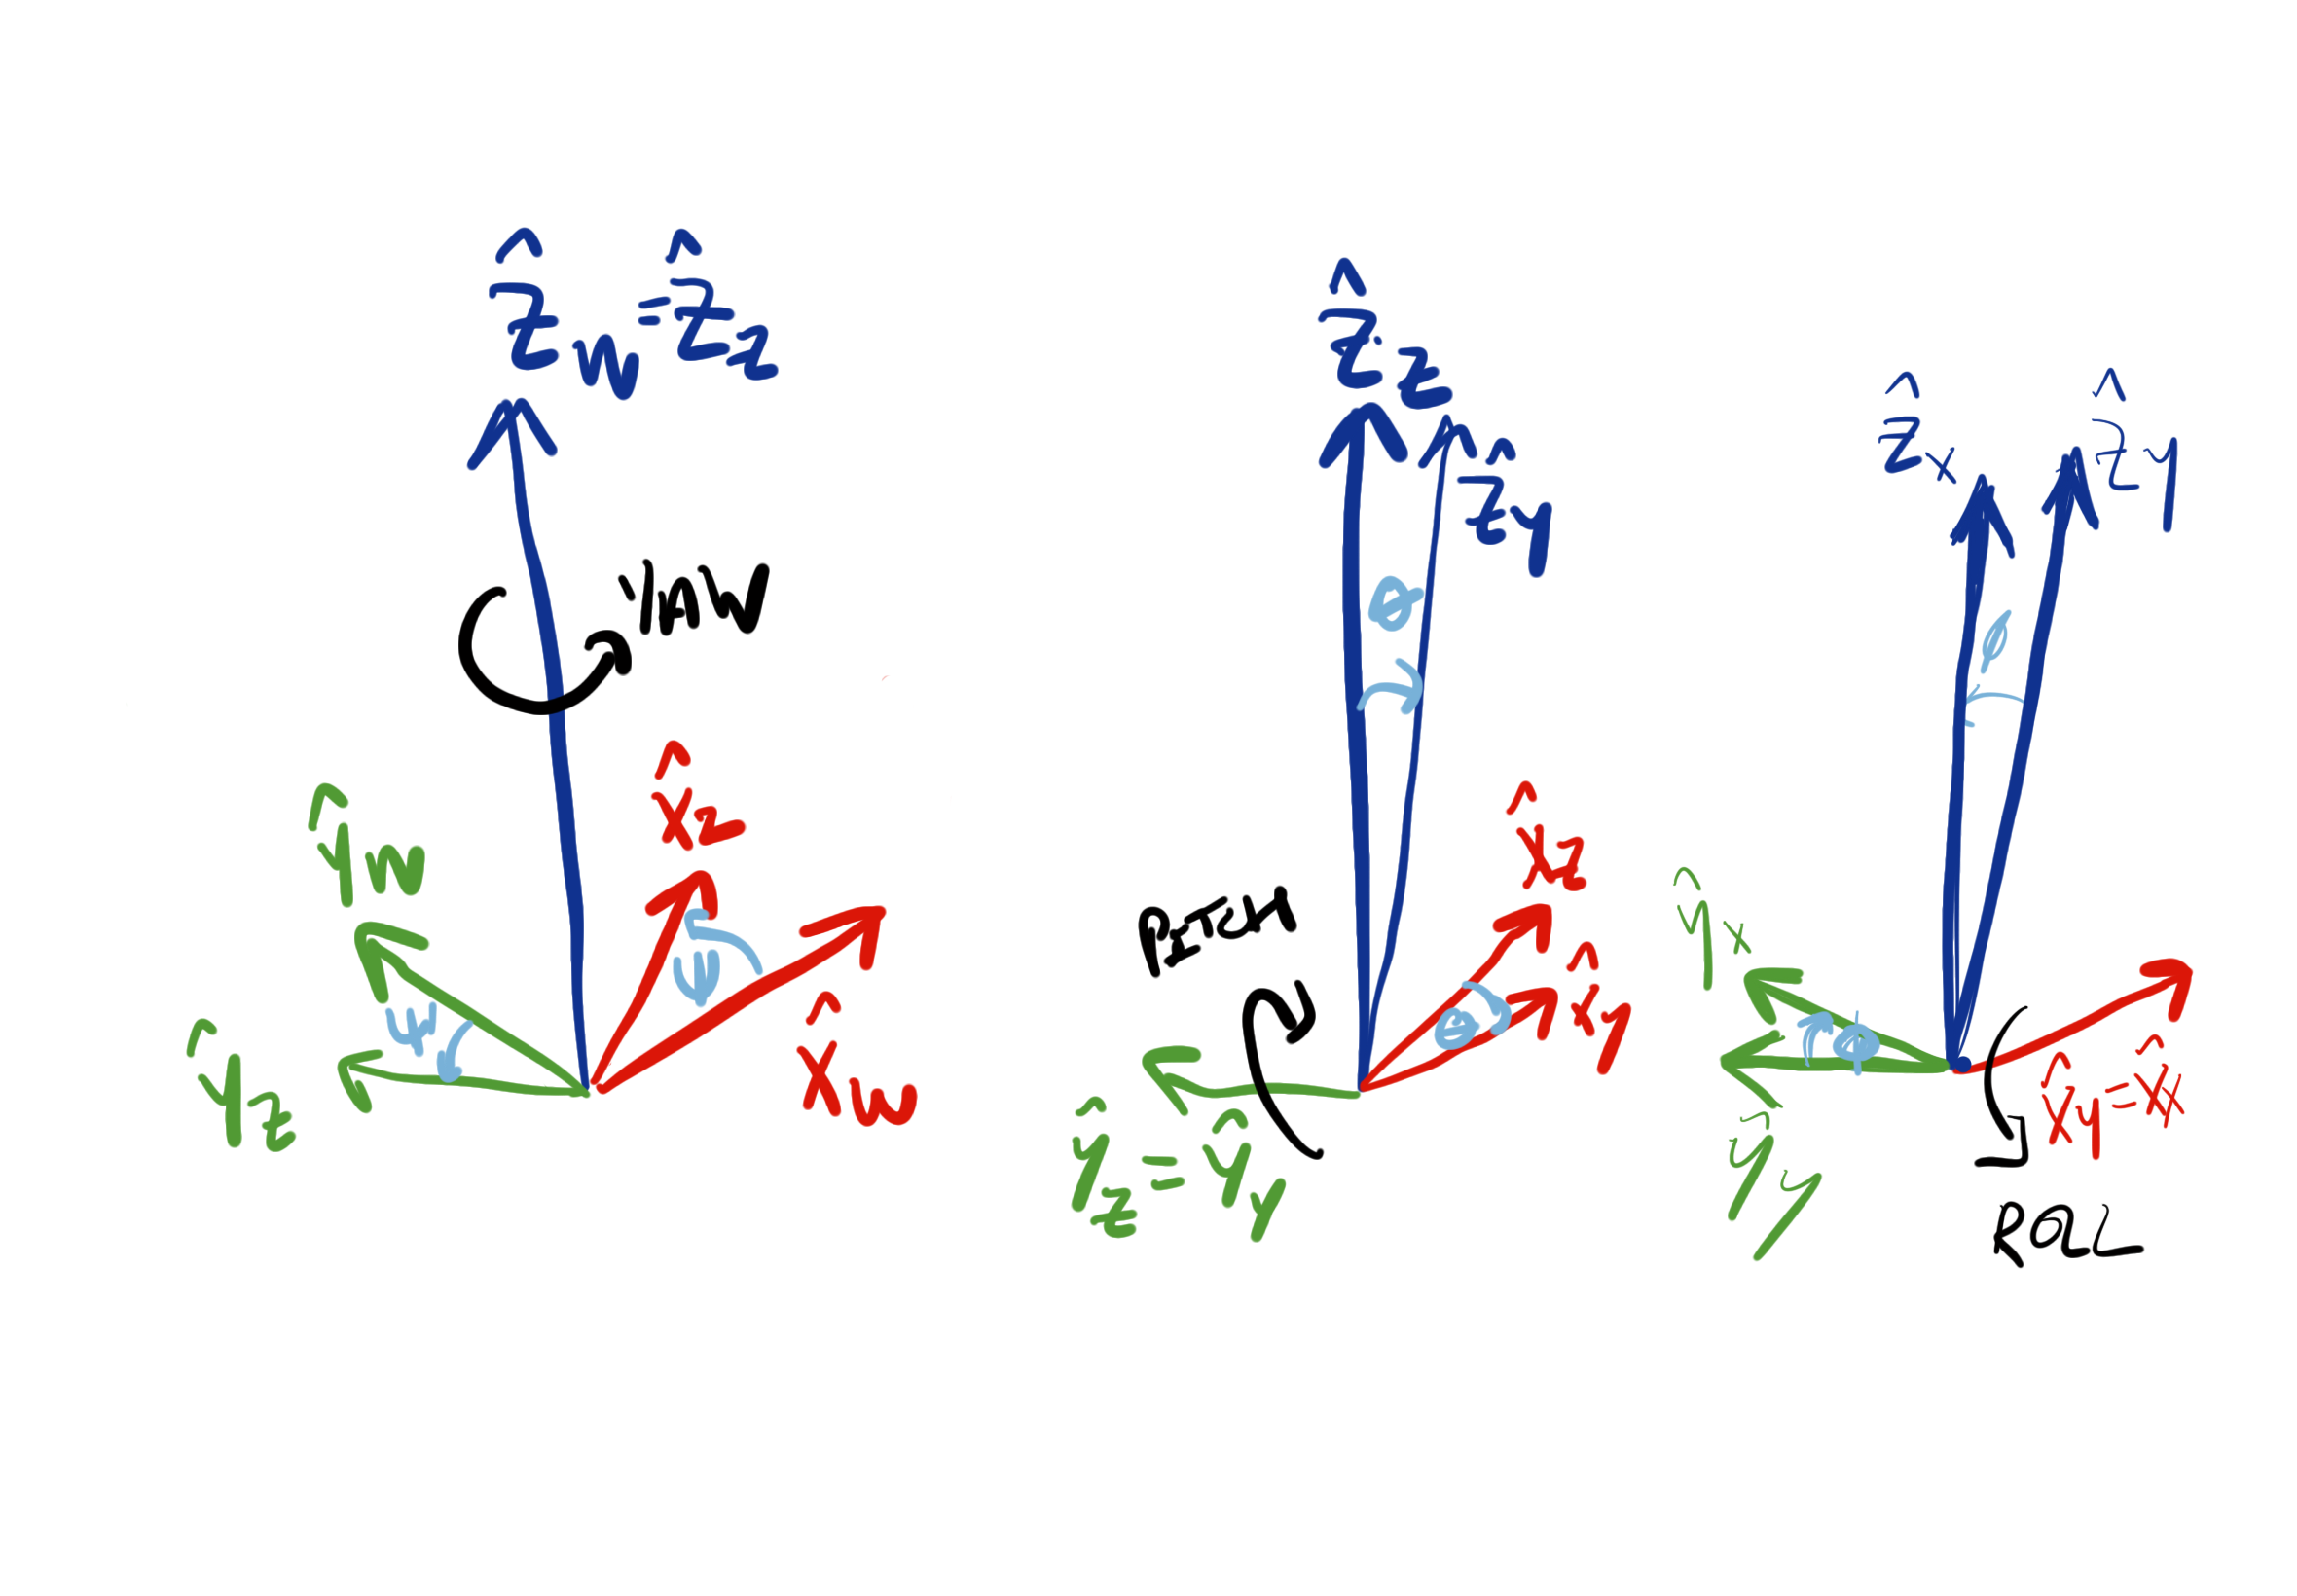

**Figure 3.7:** Intrinsic Euler ZYX rotation sequence.
 

The rotation matrix that corresponds to this rotation about  $\hat{\mathbf z}_W$, rotating from $\{W\}$ to the new frame $\{Z\}$, is 


$$\begin{array}{cc}^W{\mathbf R}_Z = \left[\begin{array}{cccccccc}    \cos{ \psi} & -\sin{ \psi} & 0 \\    \sin{ \psi } & \cos{ \psi } & 0 \\    0 & 0 & 1    \\ \end{array}\right].\\ \end{array}$$


$^W{\mathbf R}_Z$ is known as an elementary rotation and notably only affects vectors in the  $\hat{\mathbf x}_W$ - $\hat{\mathbf y}_W$ plane (the  $z$ component is unaffected). Note that we have implicitly introduced a new reference frame, $\{Z\}$, from this rotation, with the above equation describing the orientation of $\{Z\}$ relative to $\{W\}$. Following this, we then rotate about the $y$-axis of $\{Z\}$,  $\hat{\bf y}_Z$, with angle $\theta$. The incremental rotation matrix that rotates $\{Z\}$ to $\{Y\}$ is


$$\begin{array}{cc}^Z{\mathbf R}_Y = \left[\begin{array}{cccccccc}    \cos{\theta} & 0 & \sin{\theta} \\    0 & 1 & 0 \\    -\sin{\theta} & 0 & \cos{\theta}    \\ \end{array}\right].\\ \end{array}$$


We have again introduced a new reference frame, $\{Y\}$. The final step is to rotate about  $\hat{\mathbf x}_Y$ with angle $\phi$. The corresponding incremental rotational mapping from $\{Y\}$ to $\{X\}=\{B\}$ (our body-frame of interest) is


$$\begin{array}{cc}^Y{\mathbf R}_B = \left[\begin{array}{cccccccc}    1 & 0 & 0 \\    0 & \cos{\phi} & -\sin{\phi} \\    0 & \sin{\phi} & \cos{\phi}    \\ \end{array}\right].\\ \end{array}$$


We can now stitch together the sequential rotations (keeping an eye on the subscripts and superscripts to aid the multiplication order) to describe our body-frame orientation, relative to the inertial-frame: 


$$\begin{array}{cc}{^W {\mathbf R}_B} = {^W {\mathbf R}_Z}{^Z {\mathbf R}_Y}{^Y {\mathbf R}_B}.\\ \end{array}$$


This representation makes use of *intrinsic Z-Y-X Euler angles, *with the"Z-Y-X" term indicating the rotation order. The rotation sequence is termed as intrinsic as the three rotations are performed around one of the "new" reference frame principal axes. *Extrinsic Euler angles* by contrast result from performing three rotations about different combinations of the world-frame axes.

The form derived above is commonly referred to as *Tait-Bryan Angles*, or nautical *angles*. That is, we first rotated about  $\hat{\mathbf z}_W$ , followed by a rotation about  $\hat{\mathbf y}_Z$ , and finishing with a rotation about  $\hat{\mathbf x}_Y$ . Explicitly, our rotation matrix, parameterised by the Z-Y-X Euler angles, is written as


$$\begin{array}{cc}^W{\mathbf R}_B =    \left[\begin{array}{cccccccc}    \cos{ \psi} & -\sin{ \psi} & 0 \\    \sin{ \psi } & \cos{ \psi } & 0 \\    0 & 0 & 1    \\ \end{array}\right]    \left[\begin{array}{cccccccc}    \cos{\theta} & 0 & \sin{\theta} \\    0 & 1 & 0 \\    -\sin{\theta} & 0 & \cos{\theta}    \\ \end{array}\right]    \left[\begin{array}{cccccccc}    1 & 0 & 0 \\    0 & \cos{\phi} & -\sin{\phi} \\    0 & \sin{\phi} & \cos{\phi}    \\ \end{array}\right], \end{array}$$


and after performing the matrix multiplication yields 


$$\begin{array}{cc}^W{\mathbf R}_B =    \left[\begin{array}{cccccccc}    \cos{\psi}\cos{\theta} & \cos{\psi}\sin{\theta}\sin{\phi}-\cos{\phi}\sin{\psi} & \sin{\psi}\sin{\phi}+\cos{\psi}\cos{\phi}\sin{\theta}\\    \cos{\theta}\sin{\psi} & \cos{\psi}\cos{\phi}+\sin{\psi}\sin{\theta}\sin{\phi} & \cos{\phi}\sin{\psi}\sin{\theta}-\cos{\psi}\sin{\phi} \\    -\sin{\theta} & \cos{\theta}\sin{\phi} & \cos{\phi}\cos{\theta}    \\ \end{array}\right]    .\end{array}$$


syms phi theta psi real

Rz = [cos(psi) -sin(psi) 0;
      sin(psi) cos(psi) 0;
      0          0       1];
Ry = [cos(theta)   0   sin(theta);
      0          1       0;
     -sin(theta)   0   cos(theta)];
Rx = [1     0        0;
      0 cos(phi) -sin(phi);
      0 sin(phi) cos(phi)];

R = Rz*Ry*Rx

$$R = \left(\begin{array}{ccc} \cos\left(\psi \right)\,\cos\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\\ \cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right)\\ -\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) \end{array}\right)$$

While the matrix above may seem a bit overwhelming, it is important to note that we only require three variables to fully define it, namely the Euler angles - $\{ \phi, \theta, \psi \}$ , which respectively describe roll, pitch, and yaw — see Figure 3.8 for a useful mnemonic to remember the rotation axes. 

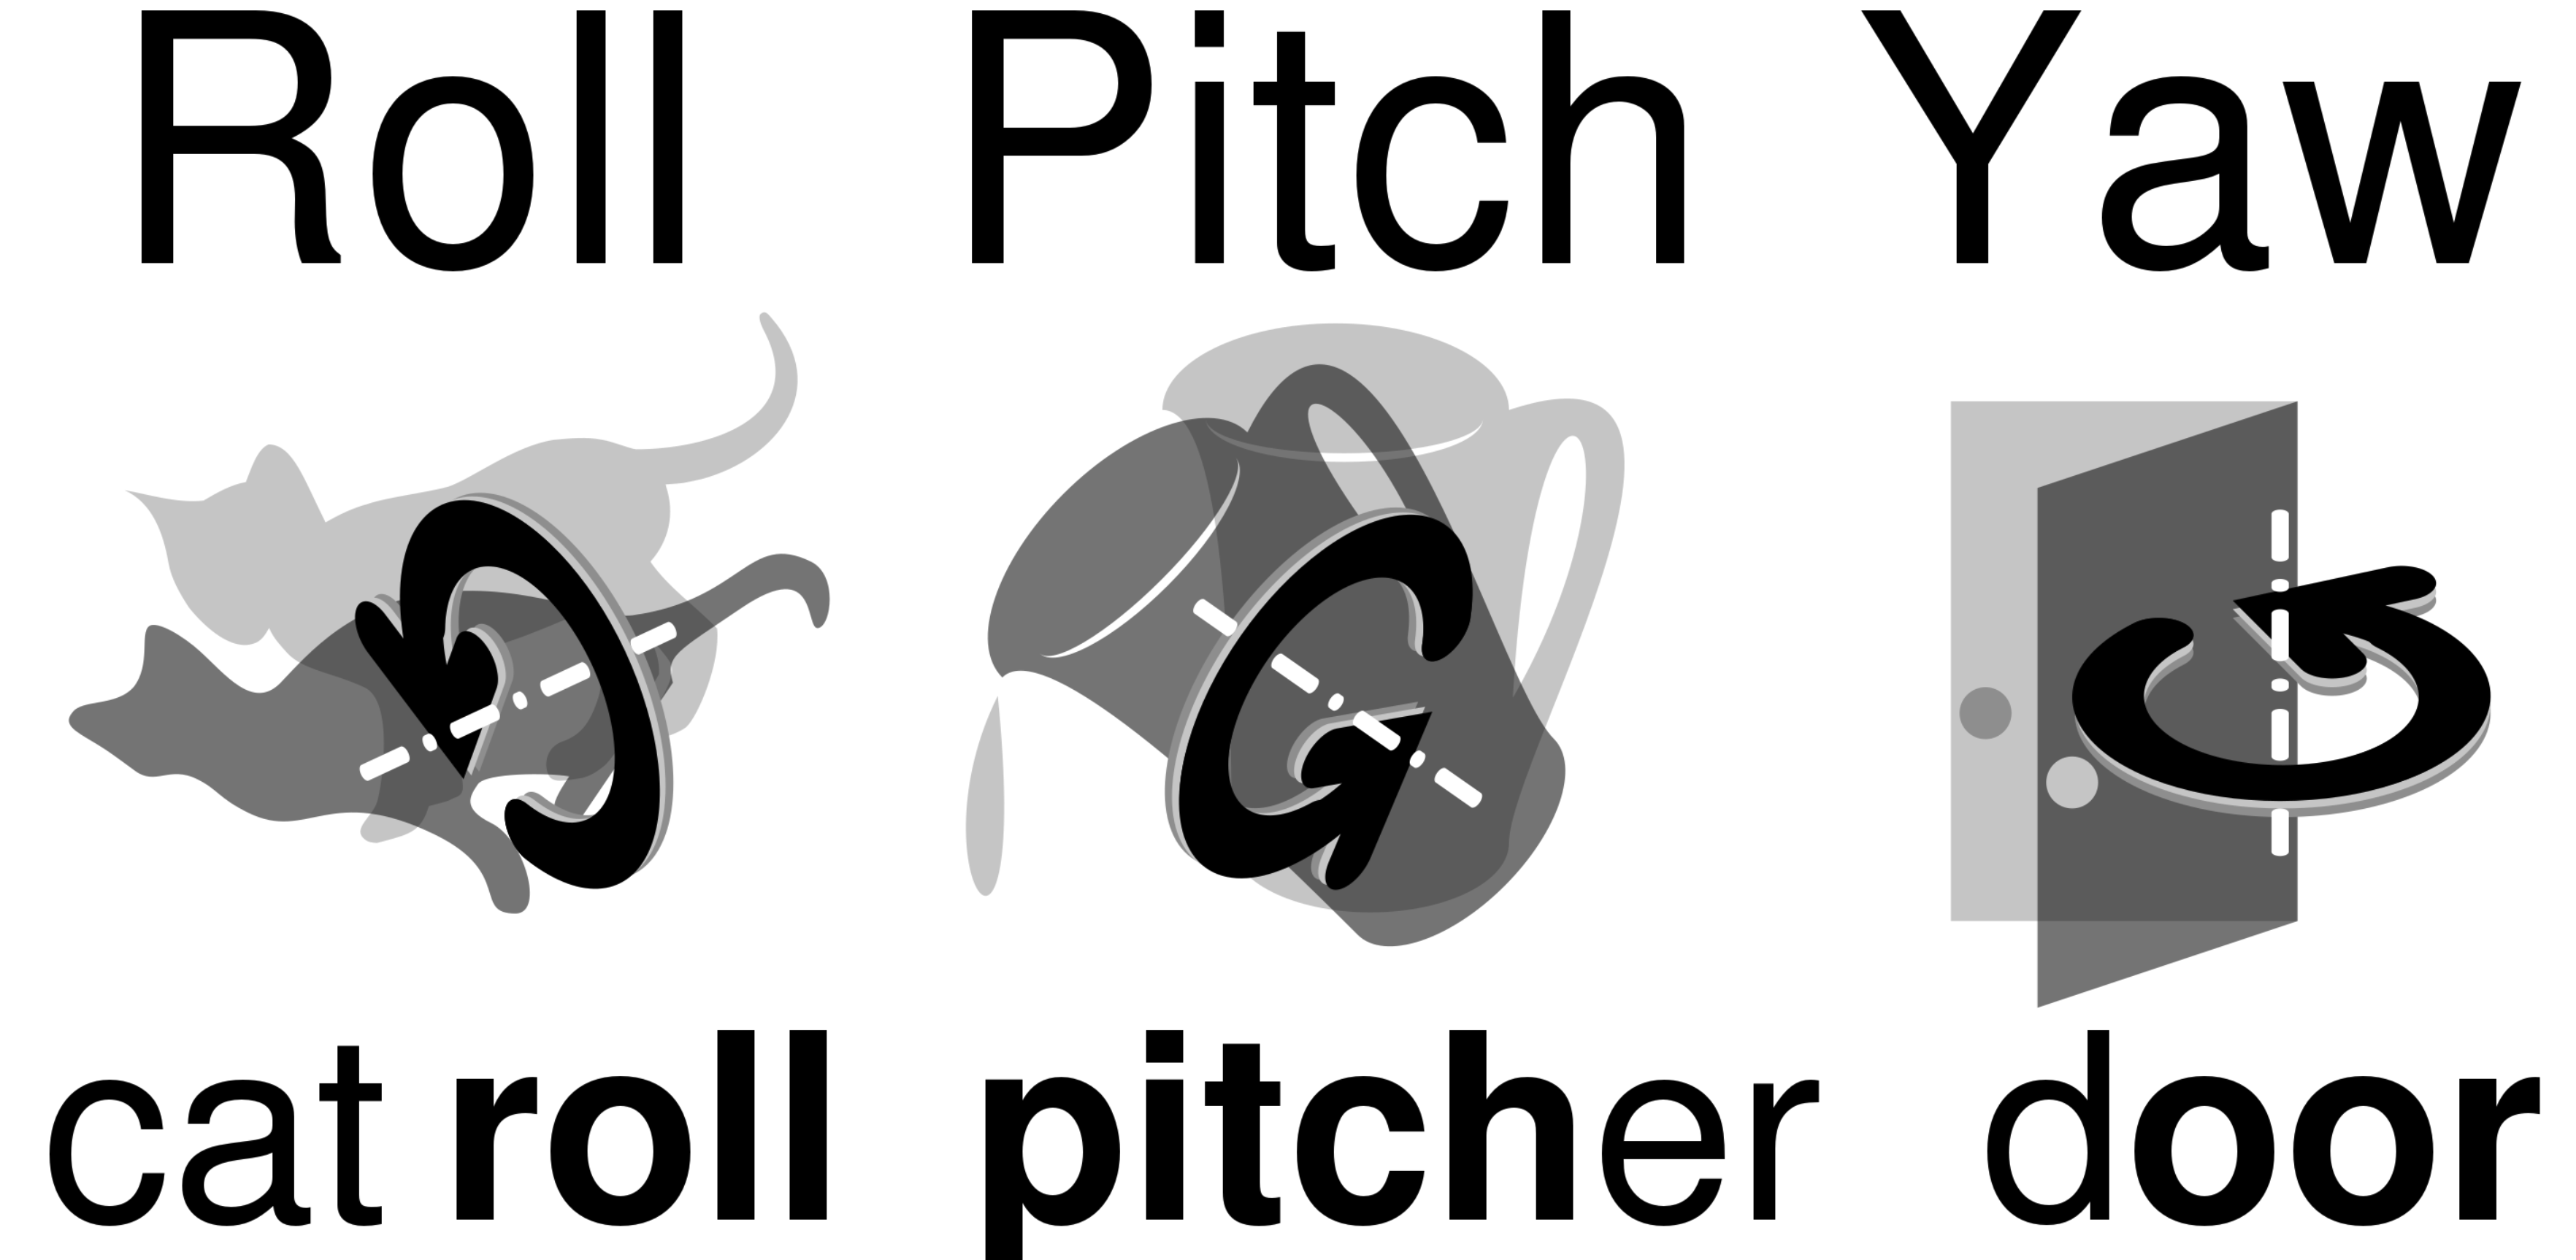

**Figure 3.8:** Mnemonics to remember the roll, pitch and yaw angle rotation axes.


The code block below can be used to visualise the workings of Euler angles in the four different frames that show the progression from $\{W\}$ to $\{B\}$, namely


$$\{W\} \rightarrow \{Z\} \rightarrow \{Y\} \rightarrow \{B\}.$$


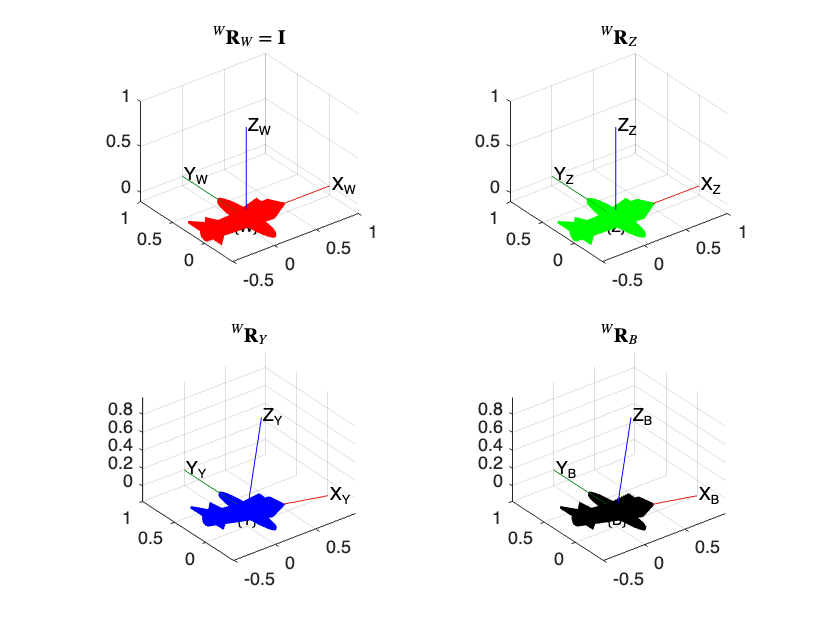

phi = 0*pi/180;
the = 10*pi/180;
psi = 0*pi/180;

Rz = [cos(psi) -sin(psi) 0;
      sin(psi) cos(psi) 0;
      0          0       1];
Ry = [cos(the)   0   sin(the);
      0          1       0;
     -sin(the)   0   cos(the)];
Rx = [1     0        0;
      0 cos(phi) -sin(phi);
      0 sin(phi) cos(phi)];

figure,hold on
subplot(2,2,1),plotTransforms([0 0 0],rotm2quat(eye(3)),"MeshFilePath",'fixedwing.stl',"MeshColor","red","FrameAxisLabels","on","FrameLabel","W")
axis equal, title('$^W{\bf R}_W={\bf I}$',Interpreter='latex'),grid on
subplot(2,2,2),plotTransforms([0 0 0],rotm2quat(Rz),"MeshFilePath",'fixedwing.stl',"MeshColor","green","FrameAxisLabels","on","FrameLabel","Z")
axis equal, title('$^W{\bf R}_Z$',Interpreter='latex'),grid on
subplot(2,2,3),plotTransforms([0 0 0],rotm2quat(Rz*Ry),"MeshFilePath",'fixedwing.stl',"MeshColor","blue","FrameAxisLabels","on","FrameLabel","Y")
axis equal, title('$^W{\bf R}_Y$',Interpreter='latex'),grid on
subplot(2,2,4),plotTransforms([0 0 0],rotm2quat(Rz*Ry*Rx),"MeshFilePath",'fixedwing.stl',"MeshColor","black","FrameAxisLabels","on","FrameLabel","B")
axis equal, title('$^W{\bf R}_B$',Interpreter='latex'),grid on

While the *Z-Y-X* rotation order is fairly common in engineering (especially aeronautics and aerial robotics), we could have actually chosen from a multitude of rotation orders. Our only constraint is that we cannot rotate about the same axis sequentially, as that would be equivalent to a single rotation by the sum of the two angles. The twelve valid rotation orders are:


$$\begin{array}{cc}    XYX, XZX, YXY, YZY, ZXZ, ZYZ, XYZ, XZY, YZX, YXZ, ZXY, ZYX\\ \end{array}$$


Different industries and manufacturers will use different conventions, but it is important to note there is technically no "right" or "wrong" version. However, one crucial point to be aware of is that an Euler angle representation of orientation always exhibits a singularity when any two rotation axes are parallel or anti-parallel. This phenomenon is commonly referred to as *gimbal lock*. 

#### **Definition: Gimbal lock**

**Gimbal lock** is the loss of one degree of freedom in a three-dimensional, three-gimbal mechanism that occurs when the axes of two of the three gimbals are driven into a parallel configuration, "locking" the system into rotation in a degenerate two-dimensional space. 

For the set of Euler angle rotation orders with repeated axes (sometimes referred to as Eulerian), namely


$$\begin{array}{cc}    XYX, XZX, YXY, YZY, ZXZ, ZYZ,  \end{array}$$


gimbal lock will occur when the second angle of rotation equals zero, as this will make the first and third rotation axis align (parallel or anti-parallel). 

For the set of Euler angles with no repeated axes (sometimes referred to as Cardian), namely


$$\begin{array}{cc}    XYZ, XZY, YZX, YXZ, ZXY, ZYX,\\ \end{array}$$


gimbal lock will occur when the second angle of rotation equals $\pm 90^\circ$, as this will make the first and third rotation axis align. 

In summary, regardless of the Euler rotation convention, gimbal lock will occur when the first and third rotation axes are aligned.

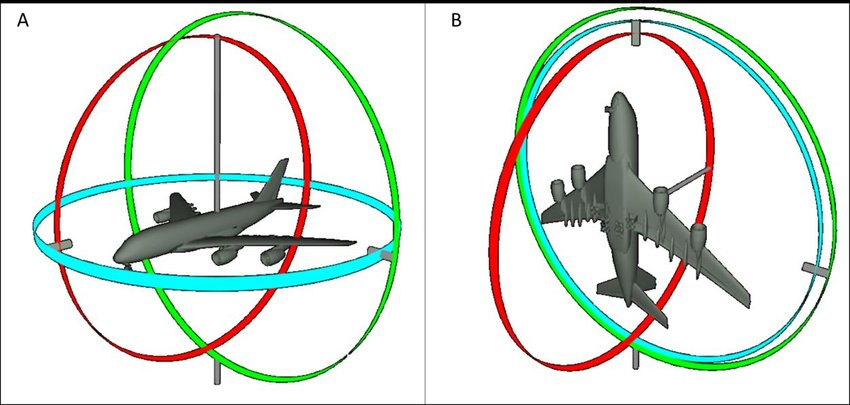

**Figure 9:** Visualisation of the three rotational axes (facilitated by imaginary gimbals) attached to an airplane. Left: nominal condition with none of the axes aligned. Right: Two of the gimbals become aligned causing a loss of information in one of the axes and resulting in a singularity \cite{phdthesis}. 
 

So if you plan to use Euler angles, you need to be cognizant of how the angular behaviour is going to evolve. If the operating region contains Euler angles that cause the first and last rotation axes to become parallel, then consider re-framing how you have defined your reference frame, or use a different rotation order to circumvent the potential for gimbal lock. [This](https://www.youtube.com/watch?v=-WXfEPg8eMM&feature=youtu.b) video provides a good explanation of gimbal lock and the singularity problem. 

#### Extracting Euler angles

The Euler-parameterised rotation matrix shows us how to populate a rotation matrix given our Z-Y-X ordering, ${^W{\mathbf R}_B}={\mathbf R}({^W\mathbf\eta_B})$, but we can also extract Euler angle information from a rotation matrix if required:  


$$^W\mathbf\eta_B={\mathbf R}^{-1}({^W{\mathbf R}_B}).$$


We may, for example, need Euler angle information to visualise how our robot is oriented, or we may want to make use of that information within a control loop (e.g. regulating the orientation of a manipulator arm). Denoting the row $x$ and column $y$ element of the rotation matrix ${\bf R}$ as $r_{xy}$, namely


$$\begin{array}{cc}^W{\mathbf R}_B = \left[\begin{array}{cccccccc}    r_{11} & r_{12} & r_{13} \\    r_{21} & r_{22} & r_{23} \\    r_{31} & r_{32} & r_{33}    \\ \end{array}\right]=    \left[\begin{array}{cccccccc}    \cos{\psi}\cos{\theta} & \cos{\psi}\sin{\theta}\sin{\phi}-\cos{\phi}\sin{\psi} & \sin{\psi}\sin{\phi}+\cos{\psi}\cos{\phi}\sin{\theta}\\    \cos{\theta}\sin{\psi} & \cos{\psi}\cos{\phi}+\sin{\psi}\sin{\theta}\sin{\phi} & \cos{\phi}\sin{\psi}\sin{\theta}-\cos{\psi}\sin{\phi} \\    -\sin{\theta} & \cos{\theta}\sin{\phi} & \cos{\phi}\cos{\theta}    \\ \end{array}\right]    .\end{array}$$


the corresponding Euler angles can be extracted using


$$\begin{array}{cc}\phi = \arctan(\frac{r_{32}}{r_{33}})\end{array},$$



$$\begin{array}{cc}\theta = -\arcsin{r_{31},\end{array}$$



$$\begin{array}{cc}\psi = \arctan(\frac{r_{21}}{r_{11}}).\end{array}$$


Importantly, this result is only valid for *Z-Y-X* intrinsic Euler angles. 

phi = -40*pi/180;
the = 10*pi/180;
psi = -80*pi/180;

Rz = [cos(psi) -sin(psi) 0; %principle rotation about z-axis
      sin(psi) cos(psi) 0;
      0          0       1];
Ry = [cos(the)   0   sin(the);  %principle rotation about y-axis
      0          1       0;
     -sin(the)   0   cos(the)];
Rx = [1     0        0;     %principle rotation about x-axis
      0 cos(phi) -sin(phi);
      0 sin(phi) cos(phi)];
R = Rz*Ry*Rx;

phi_ = atan2( R(3,2),R(3,3) )*180/pi

phi_ = -40.0000

theta_ = -asin( R(3,1) )*180/pi

theta_ = 10

psi_ = atan2( R(2,1),R(1,1) )*180/pi

psi_ = -80

### 3.2.2 Quaternions 

Euler angles are appealing as an introduction to understanding orientation, as they are intuitively pleasing and relatively easy to visualise. However, the potential for our rotation matrix becoming degenerate and resulting in kinematic singularities raises a red flag for many robotic applications. Additionally, the idea of describing an orientation using three sequential rotations does not follow how rigid-body robot motion will evolve in general. Instead, we would expect pure rotations about some arbitrary axis — enter the quaternion! The quaternion is a popular choice of encoding attitude that can completely avoid the issue of gimbal lock by rather describing the orientation as a single rotation about some defined axis that intercepts the relevant reference frame origin. At first glance, the quaternion can seem a bit daunting, but the benefits of understanding and being able to utilise it in robotics (among other fields) is worth the time investment that you may need to understand it. 

#### Definition

The quaternion, $\bf q$ , is a 4-element vector (also known as a 4-tuple) and is structured as


$$\begin{array}{cc}{\mathbf q} = \left[\begin{array}{cc}    q_0 \\ q_x \\ q_y \\ q_z    \\ \end{array}\right],\end{array}$$


in which$\{q_0, q_x, q_y,q_z\}$ are real numbers. In the context of describing orientation, we only consider *unit quaternions*, which gives us the unit-norm constraint of


$$\begin{array}{cc}q_0^2+ q_x^2+ q_y^2+ q_z^2 = 1.\end{array}$$


Explicitly, the unit quaternion follows an angle-axis structure of 


$$\begin{array}{cc}{\mathbf q} = \left[\begin{array}{cc}    \cos{\frac{\alpha}{2}} \\ \sin{\frac{\alpha}{2}} \hat{\mathbf v}     \\ \end{array}\right] =     \left[\begin{array}{cc}    \cos{\frac{\alpha}{2}} \\     \sin{\frac{\alpha}{2}} v_x \\    \sin{\frac{\alpha}{2}} v_y \\    \sin{\frac{\alpha}{2}} v_z    \\ \end{array}\right],\end{array}$$


where  $\hat{\mathbf v}=[v_x ~v_y ~v_z]^T$ is the unit-length ( $|\hat{\mathbf v}|=1$ ) rotation axis, and  $\alpha \in [-\pi,\pi)$ is the rotation angle, as shown in Figure 10. 

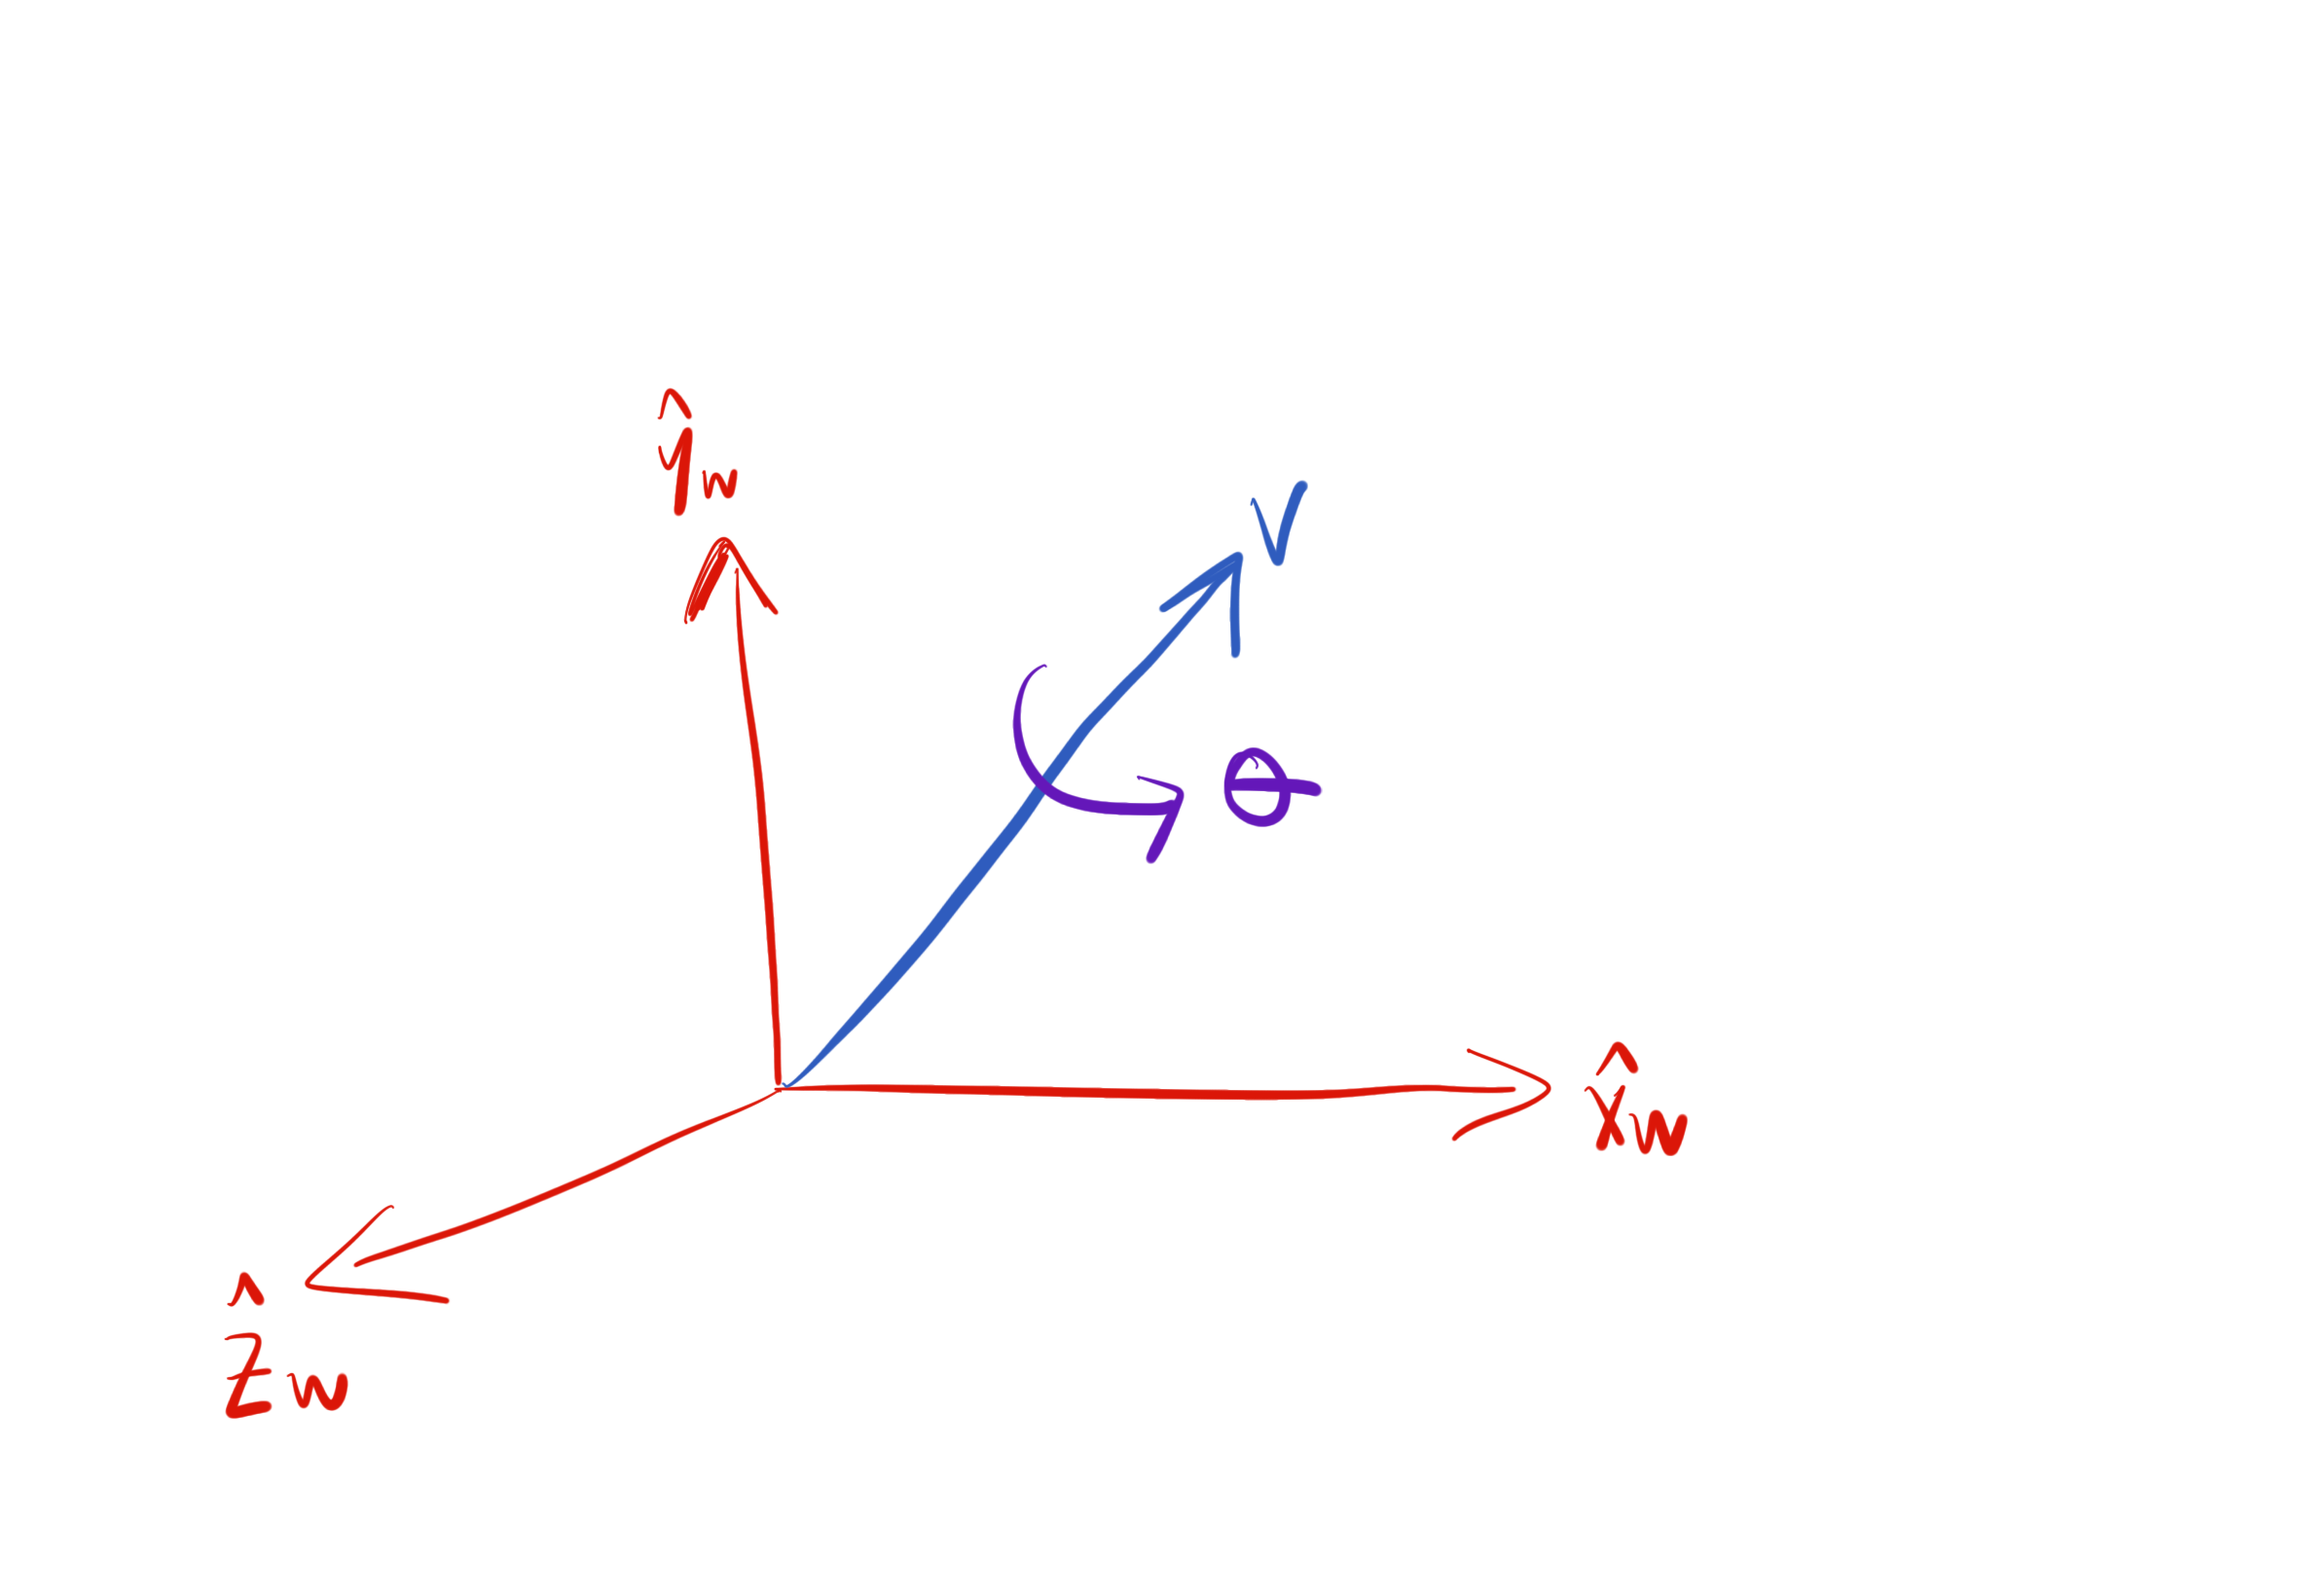

**Figure 10:** Visualisation of a quaternion-based rotation about vector $\bf v$ with rotational angle $\theta$ .
 

The equation above is a way of *encoding* the 3D rotation in a useful format, analogous to how rotation matrices encode attitude. We can always extract the angle-axis information from our quaternion representation using 


$$\begin{array}{cc}\alpha = 2\cos^{-1}(q_0),\end{array}$$


and 


$$\begin{array}{cc}\hat{\mathbf v} = \frac{1}{\sin{\frac{\alpha}{2}}}\left[\begin{array}{cc}    q_x \\ q_y \\ q_z    \\ \end{array}\right] =     \frac{1}{\sqrt{1-q_0^2}}    \left[\begin{array}{cc}    q_x \\ q_y \\ q_z    \\ \end{array}\right].\end{array}$$


When  $q_0=1$ , (which implies that  $\alpha=0$ ), the equation above tends to infinity, making the rotation axis become undefined. However, this is not problematic, as $\alpha=0$ corresponds to the null rotation matrix of  ${\mathbf R}={\mathbf I}$. In essence, we cannot determine the rotation vector because there is no rotation taking place. In this case, we would describe the identity (or null) quaternion as  ${\mathbf q}_{\mathbf I}=[1~ 0~ 0~ 0]^T$ . Given an angle-axis combination, we can now describe the corresponding quaternion


$$\{\alpha,\hat{\mathbf v}\}\rightarrow {\mathbf q},$$


and similarly, given a quaternion, we can recover our angle-axis pair


$${\mathbf q}\rightarrow \{\alpha,\hat{\mathbf v}\}.$$


For example, if we wanted to rotate about the $\hat{\mathbf z}_W$-axis by an angle $\alpha=\psi$, then our rotation axis would be  $\hat{\mathbf v}=\hat{\mathbf z}_W=[0 ~0~ 1]^T$ , resulting in


$$\begin{array}{cc}{^W{\mathbf q}}_Z = \left[\begin{array}{cc}          \cos{\frac{\psi}{2}} \\          0 \\          0 \\          \sin{\frac{\psi}{2}}          \\ \end{array}\right].\end{array}$$


Note that this quaternion is analogous to the principle $z$-axis rotation matrix of


$$\begin{array}{cc}{^W\mathbf R_Z} = \left[\begin{array}{cccccccc}    \cos{ \psi} & -\sin{ \psi} & 0 \\    \sin{ \psi } & \cos{ \psi } & 0 \\    0 & 0 & 1    \\ \end{array}\right].\\ \end{array}$$


The method of encoding the orientation is just different. Fortunately, there does exist a one-to-one mapping between the quaternion representation and rotation matrix, given by


$$\begin{array}{cc}{\mathbf R} = \left[\begin{array}{cccccccc}    2(q_0^2+q_x^2)-1 & 2(q_xq_y-q_0q_z) & 2(q_xq_z+q_0q_y) \\    2(q_xq_y+q_0q_z) & 2(q_0^2+q_y^2)-1 & 2(q_yq_z-q_0q_x) \\    2(q_xq_z-q_0q_y) & 2(q_yq_z+q_0q_x) & 2(q_0^2+q_z^2)-1    \\ \end{array}\right],\end{array}$$


and unsurprisingly, by substituting our result for ${^W{\mathbf q}}_Z$ into $\bf R$ above, we obtain $^W{\bf R}_Z$. 

#### Quaternion multiplication

While the mapping from $\bf q$ to $\bf R$ is a nice sanity check on things, we are losing one of the benefits of the quaternion, and that is its mathematical efficiency. Just as we were able to sequentially construct our body-frame orientation by using the elementary rotations when dealing with Euler angles, we can follow a similar process for the quaternion. However, we first need to cover how quaternion multiplication works. Given two quaternions, $\bf q$ and $\bf r$ , the quaternion product (or Hamilton Product), indicated using the symbol $\otimes$, is defined as


$$\begin{array}{cc}{\mathbf q} \otimes {\mathbf r} =     \left[\begin{array}{cc}    q_0r_0-q_xr_x-q_yr_y-q_zr_z \\    q_0r_x+r_0q_x+q_yr_z-r_yq_z \\    q_0r_y+r_0q_y+r_xq_z-q_xr_z \\    q_0r_z+r_0q_z+q_xr_y-r_xq_y    \\ \end{array}\right].\end{array}$$


You need not be too concerned about the finer details of this operation, just be aware that the multiplication of 4-tuples is different to what you are probably used to! Continuing with our exercise of emulating the sequential construction of our body-frame orientation as was done using ZYX Euler angles, we begin by configuring the two reference frames such that they are aligned and coincident. We then apply a rotation about  $\hat{\mathbf z}_W$ , with an angle of $\psi$, which gives us 


$$\begin{array}{cc}{^W{\mathbf q}}_Z = \left[\begin{array}{cc}          \cos{\frac{\psi}{2}} \\          0 \\          0 \\          \sin{\frac{\psi}{2}}          \\ \end{array}\right].\end{array}$$


We next rotate about  $\hat{\mathbf y}_Z$ with an angle of  $\theta$, which is encoded by the incremental quaternion of 


$$\begin{array}{cc}^Z{\mathbf q}_Y = \left[\begin{array}{cc}          \cos{\frac{\theta}{2}} \\          0 \\          \sin{\frac{\theta}{2}}\\          0           \\ \end{array}\right].\end{array}$$


Lastly, we rotate about  $\hat{\mathbf x}_Y$, with an angle of  $\phi$, which is described by the incremental quaternion of 


$$\begin{array}{cc}^Y{\mathbf q}_B = \left[\begin{array}{cc}          \cos{\frac{\phi}{2}} \\          \sin{\frac{\phi}{2}}\\          0 \\          0           \\ \end{array}\right].\end{array}$$


Our full description of the body-frame orientation, using the quaternion as our *encoder* follows as


$$\begin{array}{cc}{^W{\mathbf q}_B}={^W{\mathbf q}_Z} \otimes {^Z{\mathbf q}_Y} \otimes {^Y{\mathbf q}_B},\end{array}$$


and is analogous to the rotation matrix equivalent of $\begin{array}{cc}{^W {\mathbf R}_B} = {^W {\mathbf R}_Z}{^Z {\mathbf R}_Y}{^Y {\mathbf R}_B}.\\ \end{array}$ Note that in this particular case, our quaternions are still parameterised by the Euler angles. 

phi = 0*pi/180;
the = 10*pi/180;
psi = 0*pi/180;

q_z2w = quaternion( [cos(psi/2) 0 0 sin(psi/2)] );
q_y2z = quaternion( [cos(the/2) 0 sin(the/2) 0] );
q_b2y = quaternion( [cos(phi/2) sin(phi/2) 0 0] );

q = q_z2w * q_y2z * q_b2y

q = quaternion
      0.99619 +        0i + 0.087156j +        0k


This is not how we will usually make use of quaternions; rather, this is a demonstration of how quaternion rotation works, and its relationship with Euler angles and rotation matrices.

It is worth highlighting the numerical efficiency of the quaternion — while multiplying two rotation matrices requires 27 multiplications and 18 additions, quaternion multiplication only requires 16 multiplications and 12 additions. This may seem insignificant, but in certain applications where processing power is limited, or a large number of coordinate mappings are required (e.g. in the video game instustry) this FLOP saving is envaluable! 

As with the rotation matrix, the quaternion has an inverse, defined as


$$\begin{array}{cc}{\mathbf q}^{-1} = \left[\begin{array}{cc}    q_0 \\    -q_x \\    -q_y \\    -q_z    \\ \end{array}\right].\end{array}$$


We can think of this inverse in one of two ways: either (i) the rotation vector changes direction and points in the opposite direction, or (ii) the rotation angle changes direction. In either case, the quaternion inverse can be thought of as "undoing" a rotation. 

If we rotated our robot such that our quaternion was  ${\mathbf a}=[a_0 ~a_x ~a_y ~a_z]^T$ , followed by multiplication of the inverse,  ${\mathbf a}^{-1}=[a_0 ~-a_x ~-a_y ~-a_z]^T$ , we would return to our identity quaternion,  ${\mathbf a}^{-1}\otimes {\mathbf a}=[1 ~0 ~0 ~0]^T$ . 

alpha = 45*pi/180;
vx = [1 1 1]; 
vx = vx/norm(vx);

q = [cos(alpha/2) sin(alpha/2)*vx];

q_I = quatmultiply( quatinv(q),q )

q_I =      1     0     0     0


#### Rotating a frame

The sequential process of building a quaternion using the principal axis rotations is useful for demonstrating the parallel between rotation matrices and quaternions, but there is actually no need to ever use Euler angles when incorporating quaternions. As previously mentioned, the orientation can be defined using a rotation vector,  $\hat{\mathbf v}$ , and rotation angle $\alpha$ about  $\hat{\mathbf v}$ . In other words, we can define a mapping between two reference frames by either rotating about a single vector with a specific rotation angle (quaternion), or equivalently performing three sequential rotations about the intrinsic axes (Euler-parameterised rotation matrix). The quaternion approach is generally quite appealing for robotics, as it matches the "natural" rotational behaviour. That is, incremental rotations will occur as a single motion, not three discrete motions. Later chapters will also demonstrate that quaternions are highly beneficial when confronting the rigid-body robotic control problem, whereas Euler angles can become unreliable for large angular errors. 

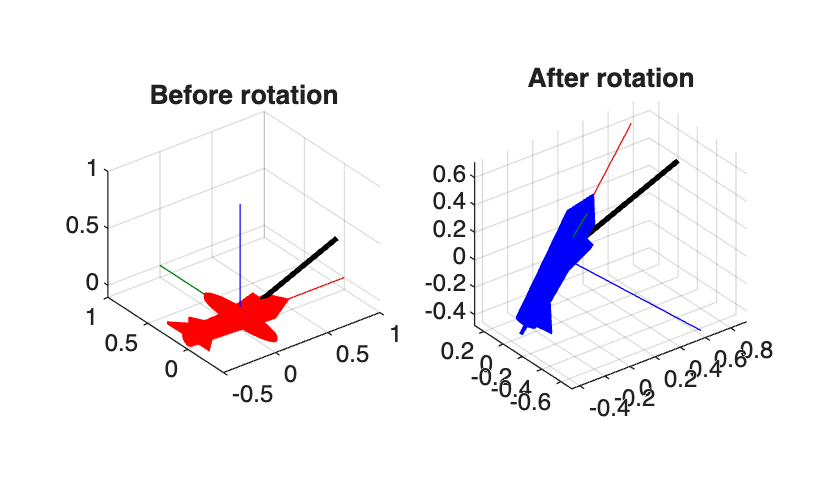

v_x = 1;
v_y = 0;
v_z = 0.4;
v = [v_x v_y v_z]'; 
v = v/norm(v);  %normalise v so that it always has unit length.

theta = 130*pi/180;
q = [cos(theta/2); sin(theta/2)*v];

figure 
subplot(1,2,1),hold on
plotTransforms([0 0 0],[1 0 0 0],"MeshFilePath",'fixedwing.stl',"MeshColor","red")
line([0 v(1)],[0,v(2)],[0,v(3)],'Color','black','LineStyle','-','LineWidth',2)
axis equal,title('Before rotation'),grid on

subplot(1,2,2)
plotTransforms([0 0 0],q',"MeshFilePath",'fixedwing.stl',"MeshColor","blue")
line([0 v(1)],[0,v(2)],[0,v(3)],'Color','black','LineStyle','-','LineWidth',2)
axis equal,title('After rotation'),grid on

#### Double cover

There is one minor caveat that should be made clear when using quaternions. We are operating in a 3D Euclidean space, but the quaternion is a 4-element vector. So why does the quaternion have 4 parameters to specify a 3D orientation? The simple answer is that a single quaternion does not uniquely define an orientation. That is, the orientation derived using a rotation about some axis is equivalent to a negative rotation about that same axis after it has been inverted. This results in a **double cover** phenomenon where  $\mathbf q$ and  $-{\mathbf q}$ represent the same rotation. 

**Proof:** You rotate an arbitrary reference frame about a specified rotation vector,  $\hat{\mathbf v}$, by some angle  $\phi$, giving us the quaternion  

${\mathbf q}_1=[\cos(\phi/2) \hat{\mathbf v}^T \sin(\phi/2)]^T$ . 

If we had decided to instead rotate about the same rotation vector but in the opposite direction with a rotation angle of  $\phi-2\pi$ , our quaternion would follow as  ${\mathbf q}_2=[\cos(\frac{\phi-2\pi}{2}) \hat{\mathbf v}^T \sin(\frac{\phi-2\pi}{2})]^T=[\cos(\phi/2-\pi) \hat{\mathbf v}^T \sin(\phi/2-\pi)]^T.$

Noting the periodic nature of the $\cos$ and $\sin$ functions, we can make use of  $\sin({x-\pi})=-\sin{x}$ and  $\cos({x-\pi})=-\cos{x}$ to reduce  ${\mathbf q}_2$ to  ${\mathbf q}_2=[-\cos(\phi/2) \hat{\mathbf v}^T -\sin(\phi/2)]^T=-{\mathbf q}_1$.

As a result of this double covering, every orientation will map to two quaternions; one that describes the minimum angle rotation, and the other describing the maximum angle rotation. The only exception is the special case where the rotation angle is $180^\circ$ , making both rotations equivalent in terms of angular distance. This disparity between a minimum and maximum angle rotation becomes important when our robot is trying to follow a path, as we commonly desire minimal angular changes that result in smaller time and energy requirements (the minimum angle rotation).

#### Rotating vectors

We have already shown that quaternions can be used to (i) represent orientation and (ii) rotate frames. Analogous to rotation matrices, quaternions also posess the third property of being able to map vectors between frames. We will not explore this in detail in this course, but the following formulation can be used to rotate a vector between two frames:


$$...$$


### 3.2.3 Exponential coordinates

...

#### **Definition:** Skew-symmetric matrix

A **skew-symmetric matrix** is a square matrix whose transpose equals its negative. 

By this definition the diagonal elements of  ${\mathbf S}$ must all equal zero in order to satisfy  ${\mathbf S}^T=-{\mathbf S}$ . Skew-symmetric matrices are useful in reposing a vector cross product operation as a matrix-vector multiplication. Given an arbitrary vector  $\mathbf\omega=[\omega_x, \omega_y,\omega_z]^T$ , the corresponding skew-symmetric matrix operator is


$$\begin{array}{cc}\lfloor \mathbf\omega \rfloor_{\times } = \left[\begin{array}{cccccccc}    0 & -\omega_z & \omega_y \\    \omega_z & 0 & -\omega_x \\    -\omega_y & \omega_x & 0    \\ \end{array}\right].& \qquad (50)\\ \end{array}$$


If we wanted to evaluate a cross product operation such as  $\mathbf\omega \times {\mathbf p}$ , we could repose it as  $\lfloor \mathbf\omega \rfloor_{\times }{\mathbf p}$ , which is a vector multiplying into a matrix (not a cross product of two vectors). However, the result would remain the same. 

## 3.3 Angular velocity

Angular velocity will dictate how our orientation changes over time, so we are therefore interested in how the two are related when dealing with multiple reference frames. This is important when mathematically modelling systems (for example when designing simulation environments) and also when angular rate information is available from a sensor (for example a gyroscope) and we want to estimate orientation from it. 

In the case of planar rotations (resulting in rotations about a fixed principle axis) the relationship is trivial, but we require more scrutiny for the generalised spatial case when up to three degrees of rotation freedom are at work.

### 3.3.1 Rotation matrix derivative

To understand the relationship between angular velocity and orientation, we need to develop a better understanding of reference frame motion as they rotate. Consider the motion of a point fixed to the end of ${^W\hat{\bf x}_B$. Recall that this describes the $x$-axis of the body frame with respect to the world frame, obtained by


$$\begin{array}{ll}
{^W\hat{\bf x}_B
&={^W{\bf R}_B\hat{\bf x}_B,\\
&={^W{\bf R}_B\left[\begin{array}{cccccccc}    1 \\    0 \\   0    \\ \end{array}\right].\\
\end{array}$$


Given the orthogonality property of ${^W{\bf R}_B$, ${^W\hat{\bf x}_B$ will always have unit length. This means that during rotation, only the direction of ${^W\hat{\bf x}_B$ will change. Given that the angular velocity of the body frame is described in the world frame as ${^W{\bf \omega}}$, we can determine the rate of change of ${^W\hat{\bf x}_B$ based on elementary mechanics, namely

${^W\dot{\hat{\bf x}}_B}={^W{\bf\omega}}\times {^W{\hat{\bf x}}_B}$.

We can repeat this process for the other two axes of $\{B\}$without loss of generality, which yields 

${^W\dot{\hat{\bf y}}_B}={^W{\bf\omega}}\times {^W{\hat{\bf y}}_B}$.

${^W\dot{\hat{\bf z}}_B}={^W{\bf\omega}}\times {^W{\hat{\bf z}}_B}$.

Recalling that


$$\begin{array}{cc}^W{\mathbf R}_B =     \left[\begin{array}{cccc}    ^W{\hat{\mathbf x}}_B & ^W{\hat{\mathbf y}}_B & ^W{\hat{\mathbf z}}_B    \\ \end{array}\right],\ \end{array}$$


the derivative of the rotation matrix follows as


$$\begin{array}{ll}^W\dot{\mathbf R}_B 
&=     \left[\begin{array}{cccc}    ^W\dot{\hat{\mathbf x}}_B & ^W\dot{\hat{\mathbf y}}_B & ^W\dot{\hat{\mathbf z}}_B    
\end{array}\right],\\
&=     \left[\begin{array}{cccc}    {^W{\bf\omega}}\times {^W\hat{\bf x}_B} & {^W\bf\omega}\times {^W\hat{\bf y}_B} & {^W{\bf\omega}}\times {^W\hat{\bf z}_B}\\
\end{array}\right].\\


\end{array}$$


Making use of our skew-symmetric form for the cross product, namely


$$\begin{array}{cc}
{{\bf \omega} \times {\bf r} = 
\lfloor {\mathbf\omega} \rfloor {\bf r}, \end{array}$$


we can express the rotation matrix derivative as


$$\begin{array}{ll}^W\dot{\mathbf R}_B 
&=     \left[\begin{array}{cccc}    {^W{\bf\omega}}\times {^W\hat{\bf x}_B} & {^W\bf\omega}\times {^W\hat{\bf y}_B} & {^W{\bf\omega}}\times {^W\hat{\bf z}_B}\\
\end{array}\right],\\
& = \lfloor {^W\mathbf\omega} \rfloor \left[\begin{array}{cccc}     {^W\hat{\bf x}_B} &  {^W\hat{\bf y}_B} &  {^W\hat{\bf z}_B}\\
\end{array}\right],\\
& = \lfloor {^W\mathbf\omega} \rfloor  {^W{\mathbf R}_B}.

\end{array}$$


This result is quite interesting as it suggests that the rate of change of our orientation encoder will be a function of both the angular velocity vector and current orientation. It can easily be shown that for any ${\bf R}\in$ SO(3) and $\bf \omega\in \mathbb{R}^3$,


$$\begin{array}{cc}\lfloor {\mathbf R}{\mathbf\omega} \rfloor = {\mathbf R}\lfloor {\mathbf\omega} \rfloor {\mathbf R}^T. \end{array}$$


Recall that we can relate the angular velocity between different frames using


$$\begin{array}{cc}{^W\mathbf\omega} = {^W{\mathbf R}_B} {^B\mathbf\omega}, \end{array}$$


and this, along with the result above of $\begin{array}{cc}\lfloor {\mathbf R}{\mathbf\omega} \rfloor = {\mathbf R}\lfloor {\mathbf\omega} \rfloor {\mathbf R}^T \end{array}$ can be used to determine the rotation matrix derivative as


$$\begin{array}{ll}^W\dot{\mathbf R}_B 

& = \lfloor {^W\mathbf\omega} \rfloor  {^W{\mathbf R}_B},\\
& = \lfloor {{^W{\mathbf R}_B}^B\mathbf\omega} \rfloor  {^W{\mathbf R}_B},\\
& = {^W{\mathbf R}_B}\lfloor {^B\mathbf\omega} \rfloor  {^W{\mathbf R}^T_B}{^W{\mathbf R}_B},\\
& = {^W{\mathbf R}_B}\lfloor {^B\mathbf\omega} \rfloor  .
\end{array}$$


Note the similarity when determining $\begin{array}{ll}^W\dot{\mathbf R}_B 



\end{array}$ as a function of $^W{\bf \omega}$ and $^B{\bf \omega}$. 

### 3.3.2 Quaternion derivative

The relationship between angular velocity and the quaternion follows a similar pattern to that of the rotation matrix counterpart. The full derivation will be spared here for sake of time. Analogous to the result of $\begin{array}{ll}^W\dot{\mathbf R}_B 

& = \lfloor {^W\mathbf\omega} \rfloor  {^W{\mathbf R}_B}

\end{array}$, the quaternion derivative can be written as 


$$\begin{array}{cc}{^W\dot{\mathbf q}_B} = \frac{1}{2}{^W\mathbf\Omega}\otimes{^W{\mathbf q}_B},\end{array}$$


where 


$$\begin{array}{ll}
{^W\mathbf\Omega}
&=\left[\begin{array}{cccccccc}    0 \\    ^W{\bf\omega}    \\ \end{array}\right]\\
\end{array}$$


is a "pure" quaternion formed from the angular velocity vector in frame $\{W\}$. Using appropriate identities, the quaternion derivative can be written as 


$$\begin{array}{cc}{^W\dot{\mathbf q}_B} = \frac{1}{2}{^W{\mathbf q}_B}\otimes{^B\mathbf\Omega},\end{array}$$


which follows a similar structure but now using the angular velocity in frame $\{B\}$. 

### 3.3.3 Estimating orientation from derivatives

The results of 


$$\begin{array}{ll}^W\dot{\mathbf R}_B 


& = {^W{\mathbf R}_B}\lfloor {^B\mathbf\omega} \rfloor  
\end{array}$$


and


$$\begin{array}{cc}{^W\dot{\mathbf q}_B} = \frac{1}{2}{^W{\mathbf q}_B}\otimes\left[\begin{array}{cccccccc}    0 \\    ^W{\bf\omega}    \\ \end{array}\right]\end{array}$$


are especially useful in robotics, as an inertial measurement unit (IMU) measures $^B\mathbf\omega$ directly. These equations can then be included in update equations to estimate orientation as the rigid-body robot experiences motion. We will explore the use of these equations in estimating orientation, as well as the topic of sensor information to accurately determine orientation in **Chapter 4**.

## 3.4 Deriving orientation error